[target, ref] = recorded_samples();

cutoff = 400;
fs = 48000;

target = highpass(target, cutoff, fs);
ref = highpass(ref, cutoff, fs);


step_sizes = [.5, .9, .9999];
ir_lens = [128, 256, 512, 1024];

N = length(ir_lens);
S = length(step_sizes);
n_iter = 20;
mses = zeros(N, S, n_iter);
preds = zeros(N, S, length(target));

out_wav = zeros(N, S, length(target));

panel_ir = clipped_irs(128, 2);
best_filt = FxLMS(ref, target, panel_ir, 256, .05);

min_mse = 100;
min_i = 0;
min_j = 0;

for i = 1:N
    ir_len = ir_lens(i);
    source_to_ref_cm = 2;

    panel_ir = clipped_irs(ir_len, source_to_ref_cm);

    panel_ir = highpass(panel_ir, cutoff, fs);


    filter_order = ir_len * 2;

    for j = 1:length(step_sizes)
    
        step_size = step_sizes(j);
    
        fxlms = FxLMS(ref, target, panel_ir, filter_order, step_size);
        fxlms.gpu = false;
        [pred_i, mses_i] = fxlms.learn(n_iter);
    
        mses(i, j, :) = mses_i;
        preds(i, j, :) = pred_i;
        out_wav(i, j, :) = fxlms.ref_filt;
        
        disp(mses_i)

        if mses_i(end) < min_mse
            min_mse = mses_i(end);
            min_i = i;
            min_j = j;
            
            best_filt = fxlms;
        end
    end

    disp('');

end

   1.0e-08 *

    0.3630    0.3208    0.3192    0.3181    0.3174    0.3169    0.3165    0.3162    0.3160    0.3158    0.3157    0.3156    0.3155    0.3154    0.3154    0.3153    0.3153    0.3153    0.3153    0.3152

   1.0e-08 *

    0.2757    0.2522    0.2502    0.2488    0.2479    0.2473    0.2468    0.2464    0.2461    0.2459    0.2457    0.2455    0.2454    0.2453    0.2452    0.2451    0.2450    0.2450    0.2449    0.2449

   1.0e-08 *

    0.2702    0.2486    0.2465    0.2451    0.2442    0.2435    0.2430    0.2426    0.2423    0.2420    0.2418    0.2417    0.2415    0.2414    0.2413    0.2412    0.2412    0.2411    0.2411    0.2410

   1.0e-08 *

    0.7043    0.5899    0.5883    0.5881    0.5883    0.5886    0.5889    0.5892    0.5895    0.5898    0.5900    0.5902    0.5904    0.5905    0.5907    0.5908    0.5908    0.5909    0.5910    0.5910

   1.0e-08 *

    0.4413    0.3852    0.3838    0.3835    0.3837    0.3840    0.3844    0.3848    0.3852    0.3856    0.3858    0.3861  

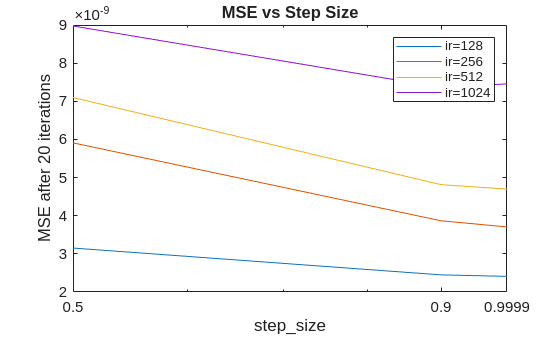

figure
plot(step_sizes, mses(1, :, end))
hold on
plot(step_sizes, mses(2, :, end))
hold on
plot(step_sizes, mses(3, :, end))
hold on
plot(step_sizes, mses(4, :, end))
set(gca, 'XScale', 'log')
xlim([step_sizes(1), step_sizes(end)])
xticks(step_sizes)

legend("ir=128", "ir=256", "ir=512", "ir=1024")
xlabel("step\_size")
ylabel("MSE after 20 iterations")
title("MSE vs Step Size")

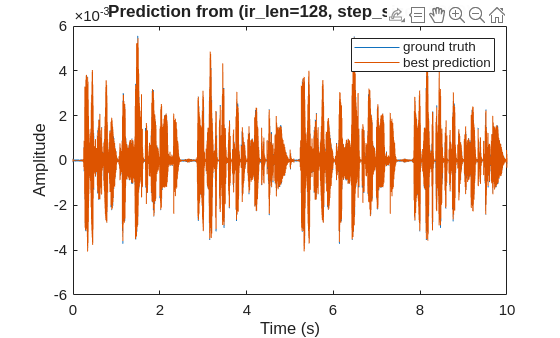

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, squeeze(preds(min_i, min_j, :)));
legend("ground truth", "best prediction")

title("Prediction from (ir\_len=128, step\_size=.9999)")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

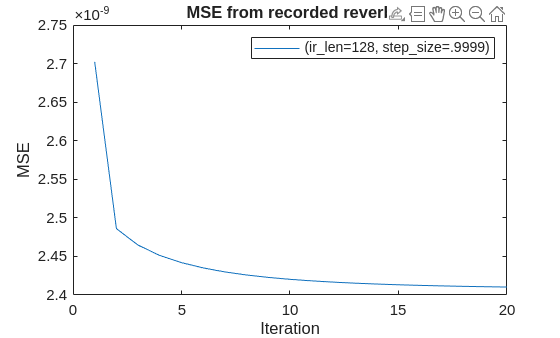

figure
plot(squeeze(mses(min_i, min_j, :)))
title('MSE from recorded reverb')
xlabel('Iteration')
ylabel('MSE')
legend('(ir\_len=128, step\_size=.9999)')

min_i % ir_length

min_i = 1

min_j % step size

min_j = 3

function save_cancel_clip(wav, filename)
    [a, fs] = arthur();
    wav = wav(1:length(a));

    disp(size(a))
    disp(size(wav))
    
    y = ([wav, a]);

    audiowrite([filename, '.wav'], y, fs);
    audiowrite([filename, '_no_cancel.wav'], [zeros(length(a), 1), a], fs);
end

for i = 1:N
    save_cancel_clip(squeeze(out_wav(i, min_j, :)), sprintf('fxlms_highpass_ir=%d', ir_lens(i)));
end

      238834           1

      238834           1

      238834           1

      238834           1

      238834           1

      238834           1

      238834           1

      238834           1



save_cancel_clip(squeeze(out_wav(4, 2, :)), sprintf('fxlms_highpass_ir=%d', ir_lens(i)));

      238834           1

      238834           1



c = CancelAnalysis('fxlms');

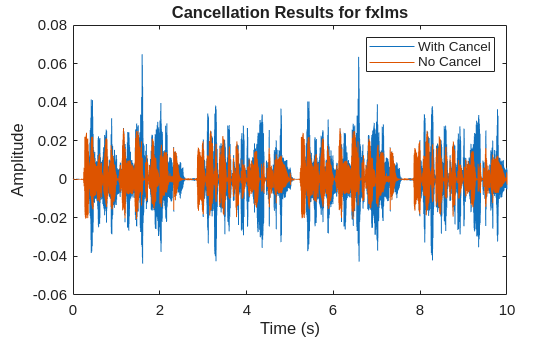

c.plot_cancel_results()